# (8). Heteronuclear Single Quantum Coherence (HSQC) experiment

### Introduction

In previous examples we have explored different 2D spectra and how we can apply apodization and phase correction to improve the quality of the signals. In both examples the phase correction values were already preset and then applied. Many NMR processing software have automatic phase correction algorithms, but often phase correction needs to be manually applied by the user. We shall explore manual phase correction to improve the quality of a Heteronuclear Single Quantum Coherence ([HSQC](https://www.sciencedirect.com/topics/chemistry/heteronuclear-single-quantum-coherence#:~:text=Heteronuclear%20single%20quantum%20coherence%20spectroscopy,the%201JCH%20coupling.)) experiment.

The HSQC experiment is a sophisticated two-dimensional NMR technique that plays a crucial role in the study of molecular structures. It is termed '*heteronuclear*' because it involves interactions between two different types of nuclei, typically 1H,13C or 15N. The '*single quantum coherence*' aspect refers to the quantum mechanical coherence between nuclear spins, which is central to the experiment. HSQC is adept at correlating directly bonded nuclei of different types, such as hydrogen and carbon, thereby elucidating which hydrogen atoms are bonded to which carbon atoms in a molecule. This is achieved through a specific sequence of radiofrequency pulses and delays designed to transfer magnetization from protons to carbon (or nitrogen) nuclei and back, resulting in a 2D spectrum with one axis representing the 1H chemical shift and the other the 13C (or 15N) chemical shift. 

The resulting peaks in this spectrum are informative about the chemical shifts of directly bonded hydrogen and carbon atoms. HSQC is particularly valuable for analyzing complex molecules, simplifying spectra, and providing high-resolution, sensitive data. It's widely used in identifying the carbon-hydrogen framework of organic molecules and in studying the structures of biological macromolecules, such as proteins and nucleic acids.

### Experimental data import

The dataset has already been exported by the NMR instrument into a .mat file that may be loaded and plotted directly. As in past tutorials we visualize the spectra with a non-linear contour plot. The HSQC experiment is phase sensitive, and we plot the real part of the spectrum. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

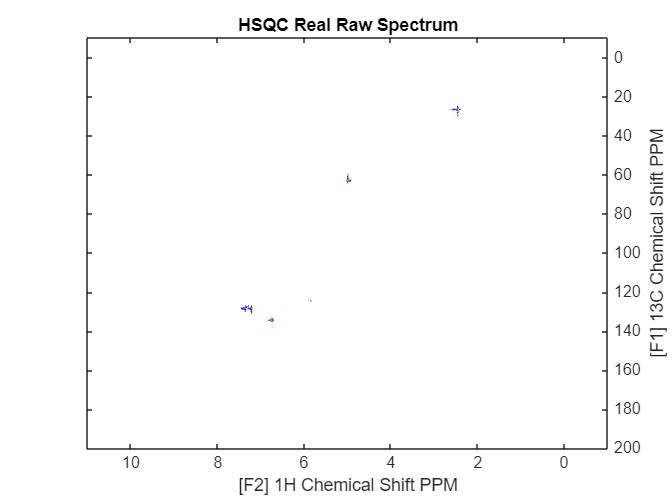

load('HSQC'); timeSpectrum=data.Data;

% Sensitive of the contour lines is non-linear and can be adjusted here
smax_real=max(real(fft2((timeSpectrum))),[],'all');
real_levels=0.95*smax_real*linspace(0,1,20).^2+0.05*smax_real;

contour(data.XAxis,data.YAxis,real((fft2((timeSpectrum)))),real_levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
title('HSQC Real Raw Spectrum'); xlabel('[F2] 1H Chemical Shift PPM');
ylabel('[F1] 13C Chemical Shift PPM'); hold on;

If you zoom into any particular peak, you will see that it is highly dispersed and out of phase. We can correct for this with appropriate apodization and phase correction.

### **Apodization**

Let us start by applying a window function to the spectrum. This is done by applying the apodization to the time domain in the F2 and F1 dimensions separately. In the example below we call a utility function which is applying a Cosine squared window to each row and column.

The cosine squared can enhance the resolution of the NMR spectrum. It does this by modulating the Free Induction Decay (FID) signal in a way that sharpens the peaks in the Fourier-transformed spectrum.

The cosine squared window function is applied with a MATLAB function call. It has the parameters: [start, end, exponent,line broadening, dimension].

By setting start at 0 end ending to pi/2 it's the cosine part of the sine function. The line broadening  parameter controls the width of the cosine curve.

- **Line Broadening  = 0.5:** This creates a narrower window, reducing the width of the main lobe.

- **Line Broadening = 1.0:** This represents the standard sine window without additional broadening.

- **Line Broadening = 1.5 and 2.0:** These values broaden the window, increasing the width of the main lobe.

% Apply a Cosine Squared Window Function
startPoint=0.5*pi;
endPoint=pi;
exponent=2;
LineBroadening=1.5;

timeSpectrum=sinWindowfunction(startPoint,endPoint,exponent,LineBroadening,timeSpectrum,'rows');
timeSpectrum=sinWindowfunction(startPoint,endPoint,exponent,LineBroadening,timeSpectrum,'columns');

### **Phase correction**

Phase correction similarly to apodization is applied to each dimension separately. To manually phase correct the spectrum, we should select a peak in the frequency domain as a reference and isolate a FID in the F2 (column) and F1 (row) dimensions. Phase correction is then applied in a standard way as if in a 1D spectra.

We see a peak at 2.5ppm and 26ppm. Let us extract that 2D region and see how it looks like.

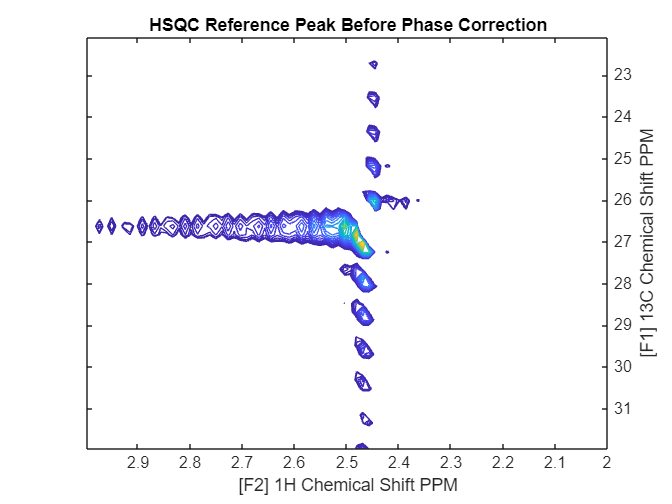

% Go back to frequency domaim
spectrum=fft2(timeSpectrum);

%  Pick a region of interest as reference for phase correction
F2_region = [3 2];
F1_region = [32 22];

% Find the index from ppm values
F2_region = findIndexFromPPM(data.XAxis',F2_region);
F1_region = findIndexFromPPM(data.YAxis',F1_region');

% Extract the regions of interest for F2 and F1 dimensions
region = spectrum(F1_region(1):F1_region(2),F2_region(1):F2_region(2));

% Lets see what the region of interest looks like
figure()
smax=max(real(region),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(data.XAxis(F2_region(1):F2_region(2)),data.YAxis(F1_region(1):F1_region(2)),real(region),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 13C Chemical Shift PPM')
title('HSQC Reference Peak Before Phase Correction')
hold on;

We can clearly see that the signal is significantly out of phase. We need to extract the 1D FID in the F1 and F2 dimensions. Within the isolated region we pick a row and a column which contains the most information. We pick Row 45 and Column 27, since that is where the center of the peak lies (picked around the middle of the square).

The direct dimension usually has more points and is easier to phase correct. You should see a live interactive figure where you can adjust the 0th and 1st order correction values with a slider (Full Screen to see both sliders). Adjust the slider values until you have centered the peak and removed the dispersion in the baseline. Once completed close the figure. The last slider values for phase correction will be remembered in the memory.

% Apply phase correction in F2 in selected region (degrees)
[F2_Final_PK0, F2_Final_PK1]=Set_Phase_Correction(region,45,'rows');

We now complete the same process in the indirect dimension. This could be more difficult since there are usually less points.

% Apply phase correction in F1 in selected region (degrees)
[F1_Final_PK0, F1_Final_PK1]=Set_Phase_Correction(region,27,'columns');

Once we have selected our 0th and 1st order phase correction values for both dimensions for that one single FID, we now apply it to every single row and column. Multiplying by rows corresponds to correction in F2 (Hydrogen dimension). Multiplying by columns corresponds to correction in F1 (Carbon dimension).

The best phase correction values can be found at: 

- **F2: **pk0=-194.4  pk1=0

- **F1: **pko=21.6    pk1=0

% Apply Phase correction with aquired values to the entire region of
% interest
corrected_spectrum = PhaseCorrection(F2_Final_PK0, F2_Final_PK1, region, 'rows');
corrected_spectrum = PhaseCorrection(F1_Final_PK0, F1_Final_PK1, corrected_spectrum, 'columns');

Now let us see the impact of phase correction on our reference peak. Clearly our peak is much more prominent.

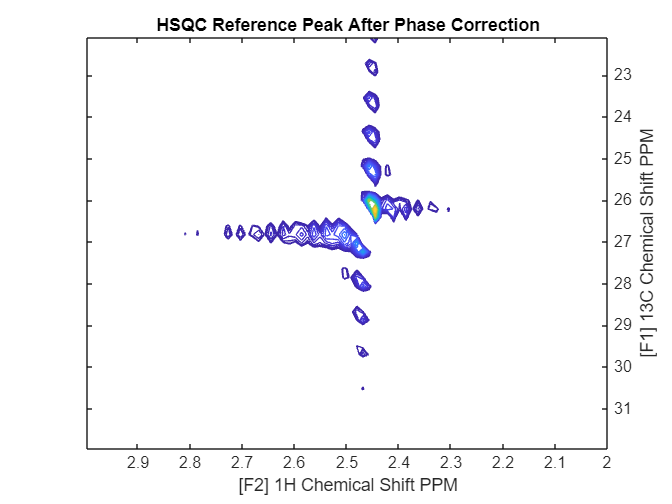

% Lets see the phase corrected region
figure()
smax=max(real(corrected_spectrum),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(data.XAxis(F2_region(1):F2_region(2)),data.YAxis(F1_region(1):F1_region(2)),real(corrected_spectrum),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
title('HSQC Reference Peak After Phase Correction')
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 13C Chemical Shift PPM')

Once we have selected the 0th and 1st order corrections which best fit the isolated peak, we apply it to the entire spectrum.  

% Convert full spectrum FID to frequency domain
signal=fft2(timeSpectrum);

% Apply Phase correction with aquired values to the entire spectrum
signal = PhaseCorrection(F2_Final_PK0, F2_Final_PK1, signal, 'rows');
signal = PhaseCorrection(F1_Final_PK0, F1_Final_PK1, signal, 'columns');

Let us look at the apodized and phase corrected HSQC spectrum. We now have very distinct peaks

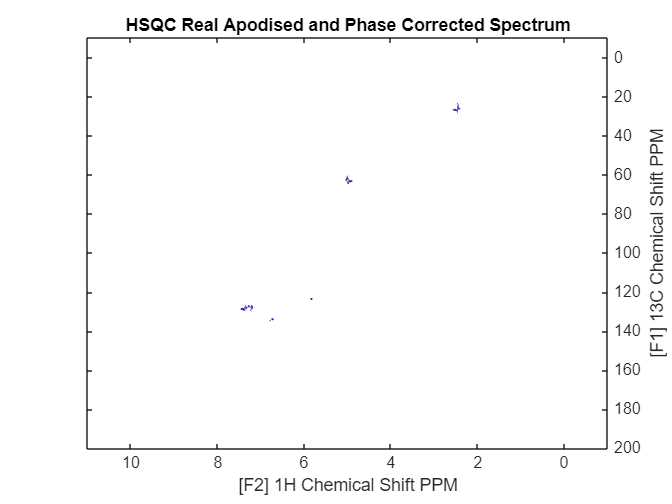

figure()
smax_real=max(real(signal),[],'all');
real_levels=0.95*smax_real*linspace(0,1,20).^2+0.05*smax_real;
contour(data.XAxis,data.YAxis,real(signal),real_levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 13C Chemical Shift PPM')
title('HSQC Real Apodised and Phase Corrected Spectrum')
hold on;

### Summary

In this tutorial, we have introduced manual 2D phase correction. Using an example of HSQC spectra, starting from the time domain we applied apodization and interactively phase corrected our entire spectra. This was done by selecting a reference peak and extracting 1D FIDs from the peak center (One for F1 and one for F2 dimensions). Then phase correction was applied interactively to select 0th and 1st order phase corrections. Once we found a good 0th and 1st order correction we applied it to the entire spectrum. 

The techniques and principles learned in this tutorial for processing HSQC spectra are not limited to this specific experiment but are also applicable to a wide range of other 2D NMR experiments. The skills acquired here form a foundational understanding of 2D NMR spectral processing, emphasizing the importance of meticulous data handling for extracting valuable molecular information from NOESY experiments. This knowledge is vital in areas such as structural biology and organic chemistry, where detailed spatial information about molecules is essential.

### **Utility Functions**

function phaseCorrectedSignal=PhaseCorrection(phc0,phc1,signal,dimension)
    switch dimension
        case 'rows'
            numPoints=numel(signal(:,1));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);

            % This multiplicity factor for 1st order correction
            phc1=deg2rad(phc1)/numPoints;         

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F1
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection;
        case 'columns'
            numPoints=numel(signal(1,:));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);
            phc1=deg2rad(phc1)/numPoints;   

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F2
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection';
    end
end

function apodisedFid=sinWindowfunction(windowfunctionStart,windowfunctionEnd,sinExponent,lineBroadining,fid,dimension)
    switch dimension 
        case 'rows' %(Multiply by rows)
            numberPoints=numel(fid(:,1));
            phiGrid=linspace(windowfunctionStart,windowfunctionEnd,numberPoints)';

            % Generate Sine Window
            sinWindowfunction=sin(lineBroadining*phiGrid).^sinExponent;
            
            % Apply Sine Window to the FID 
            apodisedFid=fid.*sinWindowfunction;
        case 'columns' %(Multiply by columns)
            numberPoints=numel(fid(1,:));
            phiGrid=linspace(windowfunctionStart,windowfunctionEnd,numberPoints)';

            % Generate Sine Window
            sinWindowfunction=sin(lineBroadining*phiGrid).^sinExponent;

            % Apply Sine Window to the FID
            apodisedFid=fid.*sinWindowfunction';
    end
end

function index=findIndexFromPPM(axis,region)
    % Calculate the absolute differences between the array elements and the target
    differencesRg1 = abs([axis - region(1);axis - region(2)]);
    
    % Find the index of the minimum difference
    [~,index] = min(differencesRg1 ,[],2);
end

function [Final_PK0, Final_PK1]=Set_Phase_Correction(region,Peak,dimension)

    % Create a figure for plotting the spectrum before and after phase correction
    fig=figure();
    tiledlayout(2,1);

    switch dimension
        case 'columns'
            % Plot the initial spectrum before phase correction
            subplot(2, 1, 1);
            plot(real(region(:, Peak)));
            title(['Column ' num2str(Peak) ' before phase correction']);
        case 'rows'
            % Plot the initial spectrum before phase correction
            subplot(2, 1, 1);
            plot(real(region(Peak,:)));
            title(['Rows ' num2str(Peak) ' before phase correction']);
    end

    % Create a button to increase the zeroth phase correction value
    PK0_Slider= uicontrol('style','slider','min',-360,'max',360,'val',0, ...
            'position',[10 10 300 30]);
    
    % Create a text label to display the zeroth order value
    PK0_Label = uicontrol('Style', 'text', 'Position', [100, 80, 200, 20],'String','PK0 Value : 0');
    
    % Create a button to increase the zeroth phase correction value
    PK1_Slider= uicontrol('style','slider','min',-360,'max',360,'val',0, ...
            'position',[2200 10 300 30]);
    
    % Create a text label to display the zeroth order value
    PK1_Label = uicontrol('Style', 'text', 'Position', [2200, 80, 200, 20],'String','PK1 Value : 0');
      
    set(PK0_Slider, 'CallBack', {@incrementValue, region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension});
    set(PK1_Slider, 'CallBack', {@incrementValue, region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension});


      % Set close function to capture final values before closing the figure
    set(fig, 'CloseRequestFcn', @closeFigure);

    % Function to capture final values before closing
    function closeFigure(~, ~)
        Final_PK0 = PK0_Slider.Value;
        Final_PK1 = PK1_Slider.Value;
        delete(fig); % Close the figure
    end

    % Wait for the figure to be deleted (closed)
    waitfor(fig);
end

% Function to increment the phase correction value and update the plot
function incrementValue(~, ~,region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension)

    PK_0 = PK0_Slider.Value;
    PK_1= PK1_Slider.Value;
   
    set(PK0_Label, 'String', ['PK0 Value: ', num2str(PK_0)]); % Update the PK0 label
    set(PK1_Label, 'String', ['PK1 Value: ', num2str(PK_1)]); % Update the PK1 label
    
    switch dimension
        case 'columns'
            corrected_spectrum = PhaseCorrection(PK_0, PK_1, region, 'columns');
            subplot(2, 1, 2);
            plot(real(corrected_spectrum(:, Peak)));
            title(['Column ' num2str(Peak) ' after phase correction']);
        case 'rows'
            corrected_spectrum = PhaseCorrection(PK_0, PK_1, region, 'rows');
            subplot(2, 1, 2);
            plot(real(corrected_spectrum(Peak,:)));
            title(['Column row ' num2str(Peak) ' after phase correction']);
    end

end